# DiD Toolbox Documentation: Tools for Difference-in-Differences Analysis

   Dr. **Ralf Elsas-Nicolle (LMU Munich, Germany,  Version as of 10/30/2025)**

## I General Overview of Purpose, Structure, and Implementation

#### Purpose

The DiD Toolbox is a set of Matlab tools designed for applied statisticians and econometricians to conduct Difference-in-Differences (DiD) analyses, particularly focusing on designs involving staggered treatment timing. The traditional Two-Way Fixed Effects (TWFE) estimator, while common, yields estimates that may be biased and difficult to interpret when treatment effects are heterogeneous across groups or vary over time. The primary goal of this toolbox is to address these methodological challenges by providing modern, robust estimators that yield valid causal estimates in complex multi-period, staggered adoption scenarios.

#### **Disclaimer**

- `The toolbox is under development, and needs more internal structure. Do use with care and be aware that the current state may not be "production ready" yet.`

- `However, I backtested all of the estimators and corresponding results using simulated data with Stata 18, utilizing implementations by Stata Corp. itself and some of the packages designed by the underlying paper's authors. Also see the provided example file, which has a Stata log-file for comparison. `

- `The Wooldridge and Callaway/Sant'Anna estimators have been tested for unbiasedness via Monte Carlo-simulation. `

- `Most of the code base was developed with the help of ChatGPT 5 Thinking. The documentation was developed also using features of NotebookLM by Google. `

`If researchers with interest in the topic and OOP skills in Matlab are interested in joining this project, I'd very much appreciate collaboration.`

#### Overview Codebase and Theoretical Foundations

The methodologies of the toolbox are grounded in foundational and recent academic literature. The software implementation uses Object-Oriented Programming (OOP) within Matlab.

**Theoretical Papers**: The toolbox implements methods developed or discussed in the following key papers:

- Goodman-Bacon (2021): Provides the mathematical foundation for the decomposition of the TWFE estimator, explaining how it operates as a weighted average of DiD estimates and identifying the source of bias from "negative weights" due to treatment effect heterogeneity.

- Wooldridge (2021): Establishes the algebraic equivalence between the Two-Way Fixed Effects (TWFE) estimator and the Two-Way Mundlak (TWM) regression, enabling flexible implementation using pooled OLS.

- Borusyak, Jaravel, and Spiess (2024): Derives the efficient and robust imputation estimator (BJS) for staggered DiD, which estimates counterfactual outcomes using only untreated observations to calculate heterogeneous causal effects, providing efficiency and avoiding spurious identification.

- de Chaisemartin and D'Haultfœuille (2020): Proposes the $$DID_M$$ estimator, which estimates a robust Average Treatment Effect across switching cells ($$\delta_S$$) and introduces robustness measures for assessing TWFE bias, particularly in designs where weights may be negative. And the unique feature is that the estimator can handle an on/off treatment, while all other estimators assume that treatment is an absorptive state.

- Callaway / Sant'Anna (2021): CS focus on cohort/time based analyses, looking at $ATT(g,k)$ with a focus on taking covariates into account. They derive identification, estimation, and inference strategies assuming parametric nuisance models (i.e. linear outcome regression, logit for propensity scores) that admit standard regularity conditions. In an extension, the interaction weighted estimator by Sun/Abraham (2021) builds on this work, showing how get unbiased event studies in this setting. 

**Codebase Structure**: The Matlab source code utilizes OOP principles under the +did/ package namespace:

- *Core Classes and Functions*: fit.m, Model.m (orchestration), getEstimator.m, Dataset.m (data management).

- *Utilities*: descData.m (descriptive statistics for DiD data), genDIDdata.m (simulation utility).

- *Estimation Modules*: Specific estimators are located in the +did/+estimators/ folder, including implementations for the *de Chaisemartin/d'Haultfœuille* estimator (ch_estimator.m), B*orusyak, Jaravel, and Spiess* (BJS) estimator (bjs_imputation.m), *Wooldridge* (TWM) estimator (wooldridge_TB.m) as well as *Callaway/Sant'Anna* (cs_estimator.m) with the extension of interaction weighing by *Sun/Abraham *(iw_estimator.m).

- Covariance Estimation: The +did/+vcov/ package handles various variance-covariance strategies, including WildBootstrap.m and Clustered.m.

#### Usage lllustrations

The toolbox provides an illustration on how to use it, available as a Matlab mlx-file and pdf in the folder "Examples":

- RealWorld_Example_DiDToolbox.mlx (with a complementary Stata 18 log-file, analyzing the same data for comparison).

## II Description of Different Tools for Analysis

### II.0    General

Throughout the toolbox, data is described by four key variables:

The function requires a panel data table (T) and mandatory name-value arguments for identifying necessary items for conducting DiD analyses (*idVar*, *timeVar*, *dVar*).

- Input data table (*T*)

- *idVar*: Identifier for units in the panel data

- *timeVar*: Time indicator

- *dVar*: Identifier per individual and time point whether treated or not (dummy)

When using commands, these are the names of input field (except for *T*), where you provide in the function call the actual (and potentially different) names of items in your data (e.g. timeVar="t"). 

You should start your analysis of data T by instantiating a validated  data object, similar to the following:

    *ds = did.Dataset.fromTable(T, idVar="id", timeVar="time", dVar="D", yVar="y",describe=true);  *

The typical command to conduct estimations then is called using *did.fit(ds,options)*

All functionality can also be called by using the full syntax similar to the following:

    *resWool =  did.fit("Wooldridge", T, idVar="id", timeVar="time", dVar="D", yVar="y",options);*

but the recommended proceeding is by using a data object.

There are three exceptions:

- Generating simulated panel data with or without different forms of treatment using* did.genDIDdata(.)*

- *did.Dataset.fromTable(.) i*s the first initiation of the data object and thus requires the definition of the data table and the key variables' names.

- The only command that is estimator specific is a plotting utility. It needs to be called based on an estimator's output (instead of the data object *ds*),:

            d*id.did_plot(resWool, "event");       % event-study*

### II.1    Simulating data

For understanding and backtesting the estimators in this toolbox (or DiD settings in general), genDIDdata.m generates data suitable for DiD analyses. It generates the outcome variable by combining components such as the base outcome (`y_base`), factoring in influences from time-varying covariates (y`X`), the true treatment effect (`tau_true`), and an error term (`epsilon`). You can set the number of individuals, how many are treated and what are the treatment effects and their time patterns.

#### Syntax

**Mandatory:*** numPeriods*, *numIds* and *percTreated *are mandatory input arguments and shall be directly provided in this order.  

The function supports different characteristics of  the treatment effects:

   ** treatType**="constant"|"constantTime"|"timeIncrease"|"onOff"

- Type "*constant*": The canonical DiD type, where all treatments have the same magnitude and happen at the same time (over time and over cohorts).

- Type "*constantTime*": Treatment is staggered, numCohort is the number of cohorts (with different start of treatment), *CohortIncrease* is the difference in ATT per cohort / first treatment time.

- Type " *timeIncrease*" increases the treatment effect within cohort over time after first treatment (*dynEffect* gives the change per period)

- Type "*onOff*" generates non-absorptive treatment, ending in *endPeriod* (a vector with length equal to *numCohorts*)

**Cohorts** can be explicitly set w.r.t *CohortTimes* (timing of treatment start), *CohortSize* (absolute size of each cohort) or *CohortProbs* (fraction of each cohort (vector length of *cohortProbs *must equal number of cohorts)

The function supports various options for **pre-trend**s, including `"none"`, `"unitLinear"`, `"unitQuadratic"`, or `"shock" (not tested yet)`.

Example

    clear;
    T = did.genDIDdata(12, 500, 0.6, ...
        treatType="constantTime", startPeriod=4, ...
        cohortTimes=[4 7 10],xNum=2,                     ... % creates x1, x2
        betaX=[0.6, -0.4],          ... % effect of x1,x2 on y
        xUnitStd=1, xTimeStd=1, xShockStd=1, CohortIncrease=1.5);

    % Instantiate data object:
    ds = did.Dataset.fromTable(T, idVar="id", timeVar="time", dVar="D", yVar="y",describe=true);  


[DataDesc] Units = 500 | Periods = 12 | Nobs = 6000 | Balanced Units = 500 (100.0%)
[DataDesc] Ever-treated = 306 (61.2%) | Never-treated = 194 (38.8%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "4"            91      0.182        0                   0                      4       
        "7"           106      0.212        0                   0                      7       
        "10"          109      0.218        0                   0                     10       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean 

**Note**: In this example, the true treatment effects are set to 2, 3.5 and 5 for the cohorts treated at time 4,7, and 10, respectively. As we know the true $$ATT(g,t)$$ in the simulated data, this allows to compare the estimated coefficients between different methods under the same degrees of data characteristics (like covariates, error term variance etc.).

#### **Output**

Key variables in the generated data table are the identifier items *id* (idVar),* time* (timeVar), *y* (yVar) and *D* (dVar), where the latter is the indicator variable for actual treatment.

### II.2    Data Description Utility

The *did.dataDesc* function provides a quick overview of the panel dataset, summarizing essential characteristics such as unit counts, time periods, treatment assignment patterns, and outcome variable descriptives.

This utility calculates descriptive statistics by identifying the panel structure, determining treatment cohorts based on their first treatment date, and classifying units as ever-treated, never-treated, or "leavers" (units whose treatment turned off after being on). If an outcome variable is provided (yVar), overall and cohort-stratified descriptive statistics are computed.

Note that it is automatically called when instantiating the data object with the option *describe=true*

#### Syntax

The function requires the panel data table (T) and mandatory name-value arguments for identifying columns (*idVar*, t*imeVar*, *dVar*).

Example

descStat = did.dataDesc(ds);


[DataDesc] Units = 500 | Periods = 12 | Nobs = 6000 | Balanced Units = 500 (100.0%)
[DataDesc] Ever-treated = 306 (61.2%) | Never-treated = 194 (38.8%) | Leavers = 0 (0.0% of ever)
Cohorts (first 6 rows):
    cohort_label    N_units    Share    N_leavers    ShareLeaversAmongCohort    FirstTreat_time
    ____________    _______    _____    _________    _______________________    _______________

        "4"            91      0.182        0                   0                      4       
        "7"           106      0.212        0                   0                      7       
        "10"          109      0.218        0                   0                     10       

Outcome Y (overall) – N/Mean/SD/Min/P25/Median/P75/Max:
     N       Mean 

#### Output

- *Overview*( table): Summarizes time range, #periods, #units, $$N_{obs}$$, balance, EverTreated, NeverTreated, and Leavers.

- *Cohorts* (table): Details on treatment cohorts (first treat time), including unit counts and leaver statistics per cohort.

- *PeriodStats* (table): Statistics by time period (units observed, treated, not-yet, never, off-after-on).

- *Y_overall* (table): If yVar is provided, overall summary statistics (N, Mean, SD, Min, Median, Max).

- *Y_by_cohort* (table): If yVar is provided, summary statistics broken down by treatment cohort (including the "never" treated group) are included.

- Options (table): Identifiers provided

### II.3    Plotting Utility

For convenience, a plotting utility *did_plot* is provided. After running an estimator of the toolbox (see the next section), one can easily make graphs of treatment effects, either aggregated over cohorts ("cohort") or over event time ("event").

#### Syntax

did.did_plot(resBJS, "cohort")

#### Example

resWool =  did.fit("Wooldridge", ds, Covariates=["x1","x2"]);

[wooldridge] ATT by cohort (mean of cohorts coefficients):
    Cohort    #TimePeriods    ATT(k)      SE       tStat       pValue   
    ______    ____________    ______    _______    ______    ___________

       4           9           2.056    0.11345    18.123     8.9917e-57
       7           6           3.434    0.10152    33.826    3.1173e-131
      10           3          5.0186    0.12275    40.886    2.0201e-161

[wooldridge] Overall ATT (cohort-share weighted):
    Estimate       SE       tStat       pValue   
    ________    ________    ______    ___________

     3.5886     0.076606    46.845    8.1177e-185

[wooldridge] ATT by event time (

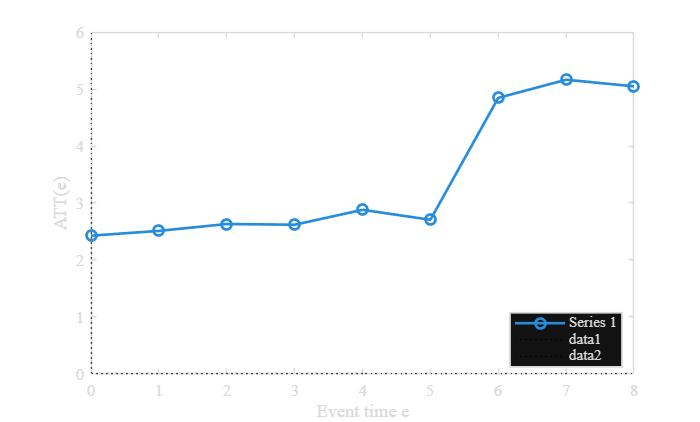


did.did_plot(resWool,"event");

### II.3    Diagnostic Tool: Bacon Decomposition

The Bacon Decomposition, based on the work of Goodman-Bacon (2021), is a necessary diagnostic tool in staggered DiD settings. The standard TWFE estimator $$\hat{\beta}_{DD}$$ is shown to be a weighted average of all possible Difference-in-Differences (DD) estimators based on the cohorts in the data. The decomposition identifies the contribution of four types of comparisons:

- Treated vs. Untreated: Compares a treated cohort to a never-treated control group.

- Early vs. Late Treated (Admissible Timing): Earlier-treated groups act as treatment, later-treated groups act as controls during their pre-period.

- Late vs. Early Treated (Forbidden Comparison): Later-treated groups act as treatment, already-treated earlier groups act as controls.

#### Role of Negative Weights

When Average Treatment Effects (ATT) vary over time ($$\Delta ATT \neq 0$$), the "Late vs. Early" (forbidden) comparisons are the primary source of negative weights. This occurs because the TWFE specification implicitly uses already-treated units as controls for later-treated units, causing changes in the outcomes of the already-treated group (which include changes in their treatment effects) to be subtracted, biasing the estimate away from the desired causal parameter (VWATT). If treatment effects are constant, weights are positive.

#### Syntax Example

res = did.fit("bacon", T, idVar="id",timeVar="time",yVar="y",dVar="D");

**Output** comprises

- *res.ByType* (aggregated decomposition) and 

- *res.Pairs *(pairwise comparisons)

Example:

res = did.fit("bacon", ds);


---- Bacon: Overall (TWFE) -----
    3.5119

Bacon: ---- Comparisons -----
               type               group1    group2     weight     estimate
    __________________________    ______    ______    ________    ________

    "Treated vs Never Treated"       4         0       0.17541     1.9989 
    "Treated vs Never Treated"       7         0       0.27243     3.4339 
    "Treated vs Never Treated"      10         0       0.21011     4.9501 
    "Treated earlier vs later"       4         7      0.031948     2.1392 
    "Treated earlier vs later"       4        10      0.065704     1.9841 
    "Treated earlier vs later"       7        10      0.076534     3.4379 
    "Treated later vs earlier"       7         4      0.063895     3.5132 
    "Treated later vs earlier"      10         4      0.065704     4.7722 
   

## III    Estimator Descriptions and Syntax

The toolbox provides implementations for the standard TWFE estimator and five robust estimators designed for staggered adoption settings.

Default for **standard errors** is always *idVar*, unless the specific estimator requires a specific method. If you want other clustering options, you have to set "vcov"= *clusterMethod*. If clustering on one or two specific variables is desired, set "clusters" (e.g. ["id", "time"]).

### III.1    Two-Way Fixed Effects (TWFE)

#### Estimation Strategy

This method fits a linear regression model using Ordinary Least Squares (OLS) including full sets of unit fixed effects ($$\alpha_i$$) and time period fixed effects ($$\beta_t$$): $$$Y_{it} = \alpha_i + \beta_t + \tau D_{it} + \epsilon_{it} \quad$$$

The estimate $$\hat{\tau}_{FE}$$ is numerically the same as the coefficient obtained from the Two-Way Mundlak (TWM) regression without covariates.

#### Use Case & Caveat 

TWFE was until recently the standard for DiD analyses, but in staggered designs with heterogeneous effects, $$\hat{\tau}_{FE}$$ identifies a variance-weighted average treatment effect on the treated plus bias terms. If negative weights occur, or weights of "forbidden" comparisons (with already treated groups) are substantial, the estimate can be misleading.

Quite generally speaking, if treatment is staggered, potentially differs between cohorts or is an on/off treatment, use the Bacon decomposition to analyze heterogeneous treatment effects of cohorts, and if it is indicated, use BJS, Wooldridge or $DID_M$ estimator (the choice depends on your use case, see the estimators' descriptions).

#### Syntax Example 

res = did.fit("twfe", T, idVar="id",timeVar="time",yVar="y",dVar="D", vcov="clustered", clusters=["id","time"]);

#### Output

The function returns only the coefficient for the interaction isTreatmentGroup * isTreated and coefficients on covariates, if provided. 

Example

res = did.fit("twfe", ds, Covariates=["x1","x2"],...
               vcov="clustered", clusters=["id","time"]);

[TWFE] ATT(D) = 3.529989
[TWFE] Standard errors clustered by id, time 
[TWFE]
  3×5 table

    Name    Estimate      SE       tStat       pValue  
    ____    ________    _______    ______    __________

    "D"         3.53    0.32699    10.796    3.4229e-07
    "x1"     0.57709    0.02026    28.485    1.1713e-11
    "x2"    -0.38881    0.01749    -22.23    1.7146e-10



### III.2    Flexible Estimator: Wooldridge (TWM)

#### Estimation Strategy

This estimator uses the algebraic equivalence of the TWFE estimator and the Two-Way Mundlak (TWM) regression. The TWM regression is a pooled OLS regression that includes the time-varying covariates, unit-specific time averages ($$\bar{x}{i.}$$) and period-specific cross-sectional averages ($$\bar{x}{.t}$$). The key is that the two-way fixed effects estimate ($$\hat{\mathbf{\beta}}_{FE}$$) is identical to the coefficient on $$x_{it}$$ obtained from the TWM regression ($$\hat{\mathbf{\beta}}_M$$).

This equivalence simplifies modeling complex heterogeneity (e.g., cohort-specific TEs, time-varying effects, and flexible covariate interactions), allowing the user to implement highly flexible versions of TWFE using the computational simplicity of pooled OLS. In the staggered case, the approach can be used to identify cohort/calendar time combinations that have causal interpretations.

Standard errors are clustered by the input "clusters". Stata uses clustering on the cohort level (then use a variable that identifies the cohorts, e.g. clusters="gvar"). Alternatively, one could use clustering on the individuals level (i.e. use e.g. clusters="id"). 

The control group for the treated observations are the never treated observations. If these don't exist, the last treated cohort is omitted and used as control for the other cohorts. 

#### Syntax:

res = did.fit("wooldridge", T, idVar="id",timeVar="time",yVar="y",dVar="D", vcov="clustered", clusters="id");

#### Output

- Overall ATT

- ATT by time

- ATT by event time

- If you set the option *details,* the full regression output with the pairwise estimates is shown

Example

res = did.fit("wooldridge", ds, Covariates=["x1","x2"],vcov="clustered", clusters=["id"]);

[wooldridge] ATT by cohort (mean of cohorts coefficients):
    Cohort    #TimePeriods    ATT(k)        SE        tStat       pValue  
    ______    ____________    ______    __________    ______    __________

       4           9           2.056    0.00087385    2352.8    0.00027058
       7           6           3.434    0.00058623    5857.8    0.00010868
      10           3          5.0186      0.000506    9918.2    6.4187e-05

[wooldridge] Overall ATT (cohort-share weighted):
    Estimate        SE        tStat      pValue  
    ________    __________    ______    _________

     3.5886     0.00064319    5579.5    0.0001141

[wooldridge] ATT by ev

### III.3    Robust/Efficient Estimator: Borusyak, Jaravel, Spiess (BJS)

#### Estimation Strategy 

BJS provides the efficient linear unbiased estimator for estimating pre-specified weighted sums of treatment effects ($$\tau_w$$) in staggered designs, allowing for unrestricted heterogeneity ($$\mathbf{\Gamma} = \mathbf{I}$$). The procedure is intuitive:

    1. Fixed Effect Estimation: Estimate unit ($$\hat{\lambda}_i^$$) and period fixed effects ($$\hat{\delta}^$$) using OLS applied only to the untreated observations ($$i,t \in \mathcal{I}_0$$).

    2. Imputation: Impute the counterfactual untreated potential outcome ($$\hat{Y}_{it}(0) = \hat{\lambda}_i^* + \hat{\delta}^*$$) for treated observations ($$i,t \in \mathcal{I}_1$$).

    3. Effect Calculation: The estimated treatment effect for each observation is $ $\hat{\tau}{it}^* = Y{it} - \hat{Y}_{it}(0)$$, which are then aggregated by the chosen weights to estimate the target $$\hat{\tau}_w^*$$.

This method is robust, avoids "forbidden comparisons," and is characterized as efficient under spherical errors. It explicitly avoids the spurious identification of long-run causal effects that plagues conventional dynamic TWFE specifications.

- Standard errors are estimated via the jackknife ("leave-one-out", LOO) method.

- If you have many individuals in the panel, you might want to set the optional parameter *useParallel* equal to the number of processors to be used with parallel processing.  

#### Syntax

res = did.fit("BJS", T, idVar="id", timeVar="time", yVar="y", dVAr="D",BootReps=0);

#### Output

The output consists of 

- the overall weighted ATT

- one table that shows ATT per cohort, weighted by number of obs cohrts (and s.e., nobs, CI).  

- More output is returned but not printed.

Example:

res = did.fit("BJS",ds, Covariates=["x1","x2"],useParallel=8);


[BJS] Untreated-only fit on ALL D==0: N_untreated = 4218 | Units = 500 | Periods = 12
[BJS] Treated identified: 1782/1782 (100.0%)
[BJS] Overall ATT = 3.0907 (SE=0.0994; 95% CI [2.8958, 3.2856])
ATT by Cohort
    cohort    ATT_obs    SD_obs    N_obs     SE_obs     CI_lo_obs    CI_hi_obs
    ______    _______    ______    _____    ________    _________    _________

       4      2.0559     1.6724     819     0.058439     1.9412       2.1706  
       7      3.4301     1.6417     636     0.065097     3.3023       3.5579  
      10      5.0222     1.5823     327       0.0875     4.8501       5.1943  



### III.4    Robust Estimator: de Chaisemartin/D'Haultfœuille Estimator (DID_M)

#### Estimation Strategy 

The DID_M estimator targets $\delta_S$, the Average Treatment Effect (ATE) across all "switching cells"—groups whose treatment status changes between $ $t-1$$ and $$t$$. This is calculated as a weighted average of two specific DiD terms:

    ◦ $$DID_{+,t}$$: Compares joiners (treatmen t$ $0 \to 1$$) to groups remaining untreated.

    ◦ $$DID_{-,t}$$: Compares leavers (treatment $$1 \to 0$$) to groups remaining treated.

$$DID_M$$ is valid under heterogeneous treatment effects and inherently avoids the source of negative weighting bias by strictly contrasting switching groups against stable groups. In staggered adoption designs, where treatment is typically irreversible,$ $DID_M$ $is a weighted average only of the $$DID_{+,t}$$ estimators.

**Note** 

- Contrary to the TWFE, Wooldridge and BJS estimators, DID_M measures treatment effects only at the period of entry and exit, i.e. not over all periods of treatment. 

- $DID_M$ is the only estimator (to my knowledge) which can handle on/off-treatments. i.e. not assuming that treatment is an absorptive state. 

- As the standard errors are determined by a jackknife bootstrap ("leave one out", LOO), this can take some time depending on the group size of the clustering variable. If the parallel toolbox is available, you can calculations speed up by setting the option *"useParallel"=true*. 

#### Diagnostic

The Placebo$ $DID_M$$ ($$DID_{M,pl}$$) is computed, comparing pre-switch outcome trends ($$t-2$$ to $$t-1$)$ for switching groups versus stable groups. A significant placebo estimate suggests the parallel trends assumption (Assumptions 4, 5, 9, and 10 in the paper) is violated.

#### Syntax 

resDIDM = did.fit("DID_M", T, idVar="id", timeVar="time", yVar="y", dVAr="D");

#### Output

The function returns 

- an overall weighted estimate of the ATT (labeled DID_M) and separate coefficient estimates for "Joiner_Only" and "Leavers_only". I addition, the weighted overall estimate for the placebo test is provided (Placebo_DIDI_M).

- the coefficients for each cohort, differentiated by the period of entry (DID_plus) and end of treatment (DID_minus).

Example:

res = did.fit("DID_M", ds,Covariates=["x1","x2"]);


=== DID_M summary (table) ===
              Effect               Estimate      SE          t           p     
    ___________________________    ________    _______    _______    __________

    "DID_M"                            3.44    0.15607     22.041     1.096e-75
    "Joiners-only"                     3.44    0.15607     22.041     1.096e-75
    "Leavers-only"                        0          0        NaN           NaN
    "Overall (cohort-weighted)"        3.44    0.14648     23.485    1.0635e-82
    "Placebo DID_M"                0.036725    0.13381    0.27445       0.78385


=== DID_M by Cohort (table) ===
    t     DID_plus    DID_minus
    __    ________    _________

     4     2.0849        NaN   
     

### III.5    Callaway / Sant'Anna 2021 (CS)

#### Estimation Strategy

In panels where units adopt at different times (or never), Callaway/Sant’Anna (CS) compute treatment effects for each cohort–time cell, written ATT(g,t): “the average effect at calendar time *t* for the cohort first treated in *g*.” This avoids the mixing issues of classic TWFE when effects vary over time or across cohorts. 

- Groups of comparison are "never" or "notyet" treated. 

- As outcomes can move before formal adoption, you can set Delta = δ ≥ 0 to exclude the δ periods before adoption from the pre-treatment baseline (*Delta*). The baseline becomes r = g − δ − 1 (instead of g − 1).

- Standard errors are estimated by a wild bootstrap type of method (e.g. *SEMethod="multiplier"*) or clustered on the unit level (SEMethod="clustered"). If there is another time-invariant source of heterogeneity between groups of data, a second cluster variable can be used.

Four possible estimation approaches are:

- *unconditional*: no covariates are taken into account (*Approach="unconditional"*).

- *OR*: Outcome regression, not taking control variables into account (*Approach="OR"*). 

- *IPW*: Uses inverse probability weighting for handling the covariates**. **Estimates propensity Pr(G=g | X), reweights controls to match treated covariates, and compares mean changes (*Approach="IPW"*).

- *DR*: Combine OR and IPW (doubly robust), i.e. adjust treated by an outcome model and weight control residuals by propensities. If only one of the two models are corrected, ATT estimates will be unbiased  (*Approach="DR"*). 

Note that with covariates, DR is the recommended ioption, as Sat'Anna/Zaho (2020) show that even if none of the two approaches are correct, the still perform better than either of the single model approaches.

#### Aggregations

In a recent paper, Deb et al. (2025) show that Stata's implementation of the CS estimator uses weights for aggregation based on 

- the number of treated observations in cohort c at treated time t (t>c), and

- the number of pre-period reference count for each post cell

This Deb et al. (2025) show that this can distort estimation of the overall ATET for repeated cross-sections (and was not suggested by CS):

- *Balanced panels***:** no problem - the two formulas coincide because $Nct=Nc,c-1N_{ct}=N_{c,c-1}Nct=Nc,c-1$� for each cohort and time. 

- *Repeated cross-sections with varying cell sizes***:** differences arise because $N_{ct}$ varies over $t$. The Stata weight adds a time-invariant pre-period count to each post cell, changing relative weights across $(c,t)$ 

- *Big pre-period relative to post-period sizes***:** the distortion is largest when the pre-period sample for a cohort is large relative to its post-period sizes. (In their simulation, this pushes more weight onto later post periods and raises the aggregated ATET.) 

- *Heterogeneous effects over cohorts/time***:** the more treatment effects vary across $(c,t)$, the more harmful the wrong weights become; if all ATTs were equal, weighting wouldn’t matter. 

- *Declining treated sample sizes over time*: particularly prone to bigger gaps between the correct and Stata’s aggregation. 

- *Not just “overall”***:** the same weighting issue also affects event-time, by-cohort, and calendar-time averages. 

The DiD Toolbox does not use the counts of pre-period observations for weighting. Instead it offers the options

- *Weighting="treatedObs",* which is the preferred  weighting aschem by Deb et al. (2025) and the default, or alternatively

- *Weighting="cohortShare"*, cohort-share weights that are constant across a cohort’s post-treatment periods.

#### Models with covariates (Sant'Anna/Xu 2025)

When using Outcome Regression (OR), Inverse Probability Weighting (IPW), or Doubly Robust (DR), one is fitting nuisance models:

-   OR: regression of ΔY on X for controls

-   IPW: logistic regression for Pr(G=g|X)

-   DR: both

If one uses the same sample to both estimate the nuisance functions (regressions / propensity scores) and to plug them into the ATT formula, ones risks overfitting. This bias can be especially bad when:

- X is high-dimensional

- The nuisance models are complex (ML, flexible nonparametrics)

The input parameters *CrossFit *(together with *Kfolds*) uses the kFold estimation by (Chernozhukov et al. 2018, "Double/Debiased ML") to split the sample into k folds, where one subsample is held out of the estimation. In the end, ATTs are constructed from recombining the estimates. Setting *StratifyFoldsBy="cohort" *keeps a similar share of each cohort in every fold.

The default for CrossFit is *false*, however, as the logistic regression is well behaved in most cases.

#### Syntax

    resCS = did.fit("cs", ds, ...
               Comparison="never", Delta=0, Approach="dr", Covariates=["x1","x2"], ...
                Seed=42, SEMethod="multiplier");

[CS] R=18 cells; Approach=dr; Comp=never; δ=0; SE=multiplier; W=treatedObs. Bootstrap B=100, crit(95%)=2.918
[CS] Overall ATT 
  1×6 table

    Estimate      SE       tStat     pValue      LB        UB  
    ________    _______    ______    ______    ______    ______

     3.1453     0.12944    24.299      0       2.8996    3.3911

[CS] Estimates 
  18×11 table

          Name             Effect      Estimate    g     t       SE       tStat     pValue    gYear    tYear    refYear

#### Output

  resCS2 = did.fit("cs",ds, ...
               Comparison="never", Delta=0, Approach="dr", Covariates=["x1","x2"], ...
                Seed=42, SEMethod="multiplier");

[CS] R=18 cells; Approach=dr; Comp=never; δ=0; SE=multiplier; W=treatedObs. Bootstrap B=100, crit(95%)=2.918
[CS] Overall ATT 
  1×6 table

    Estimate      SE       tStat     pValue      LB        UB  
    ________    _______    ______    ______    ______    ______

     3.1453     0.12944    24.299      0       2.8996    3.3911

[CS] Estimates 
  18×11 table

          Name             Effect      Estimate    g     t       SE       tStat     pValue    gYear    tYear    refYear

## III.VI    Interaction Weighted  (IW)

#### Estimation Strategy

The IW estimator was suggested by Sun/Abraham (2021) and is similar to Callaway/Sant'Anna in separating essentially ATT(g,t) estimation to avoid "forbidden" comparisons between treated and untreated observations. It can be interpreted as a clean event-study aggregator built on cohort-specific DiD contrasts ($$ATT(g,t)$)$ that respects heterogeneity and avoids TWFE pitfalls.

In the toolbox, it is identical to and builds on the CS estimation (*Approach="unconditional", Comparison="notyet", δ chosen*), but it uses a special weighting scheme for the event time aggregation. This *interaction-weighted aggregation (IW) a*ggregates across cohorts at each event time using cohort weights (e.g., cohort shares among treated), producing the event-study series θ(e)\theta(e)θ(e). This is the “IW” part: one weighs cohort×event-time interactions, not the raw outcomes.

IW does not use covariates. If this is relevant, use CS with the OR, IPW or DR option.

#### Syntax

As the IW estimator builds on CS, options are similar, in particular the choice for clustered or bootstrapped standard errors.

resIW = did.fit("iw", T, idVar="id", timeVar="time", yVar="y", dVar="D", Comparison="notyet", Delta=0, SEMethod="multiplier", B=999, Seed=42,              Multiplier="mammen");

#### Output

resIW = did.fit("iw", ds, ...
                Comparison="notyet", Delta=0, SEMethod="multiplier", ...
                B=999, Seed=42, Multiplier="mammen", Weighting="cohortShare");

[IW] IW (notyet; δ=0, SE=multiplier; W=cohortShare)
[IW] K=9 event-time points. 
    e    Estimate      SE       tStat     pValue      LB        UB  
    _    ________    _______    ______    ______    ______    ______

    0     3.4044     0.15136    22.492      0       2.9961    3.8126
    1     3.6849     0.15436    23.872      0       3.2686    4.1012
    2      3.773     0.14763    25.557      0       3.3748    4.1712
    3     2.7589     0.20777    13.279      0       2.1985    3.3193
    4     3.0117     0.20444    14.732      0       2.4603    3.5631
    5     2.9014      0.1969    14.736      0       2.3704    3.4325
    6     2.1764      0.3227    6.7443      0        1.306    3.0468
    7     2.0264     0.30691    6.6026      0       1.1986 

## IV    Usage Guidelines

## V    References

- Baker, A. C., Larcker, D. F., & Wang, C. C. Y. (2022). How Much Should We Trust Staggered Difference-In-Differences Estimates?, Journal of Financial Economics, 144, 370–395.

- Borusyak, K., Jaravel, X., & Spiess, J. (2024). Revisiting Event-Study Designs: Robust and Efficient Estimation, Review of Economic Studies, 00, 1–33.

- Deb, P. / Norton, E. / Wooldridge, J. /  Zabel, J. E. (2025) :Aggregating Average Treatment Effects on the Treated in Difference-in-Differences Models, NBER Working Paper No. 34331, October 2025. 

- Callaway, B. / Sant'Anna, P. (2021). Difference-in-Differences with Multiple Time Periods. Journal of Econometrics, 225(2), 200–230.

- de Chaisemartin, C., & D'Haultfœuille, X. (2020). Two-Way Fixed Effects Estimators with Heterogeneous Treatment Effects, American Economic Review, 110(9), 2964–2996.

- Chernozhukov et al. (2018): Double/debiased machine learning for treatment and structural parameters, Econometrics Journal 21, 1-68.

- Goodman-Bacon, A. (2021). Difference-in-differences with variation in treatment timing, Journal of Econometrics, 225(2), 254–277.

- Sant’Anna, P. /  Xu, Q. (2025): Difference-in-Differences with Compositional Changes*, *Arxiv 2304.13925.

- Sant'Anna, P. / Zhao, J. (2020): Doubly robust difference-in-differences estimators, *Journal of Econometrics*, *219*(1), 101-122. 

- Sun, L. / Abraham, S. (2021): Estimating dynamic treatment effects in event studies with heterogeneous treatment effects, Journal of Econometrics 225, 175-199.

- Wooldridge, J. (2021). Two-Way Fixed Effects, the Two-Way Mundlak Regression, and Event Study Estimators. Working Paper.